#### Time Reversal Visualization

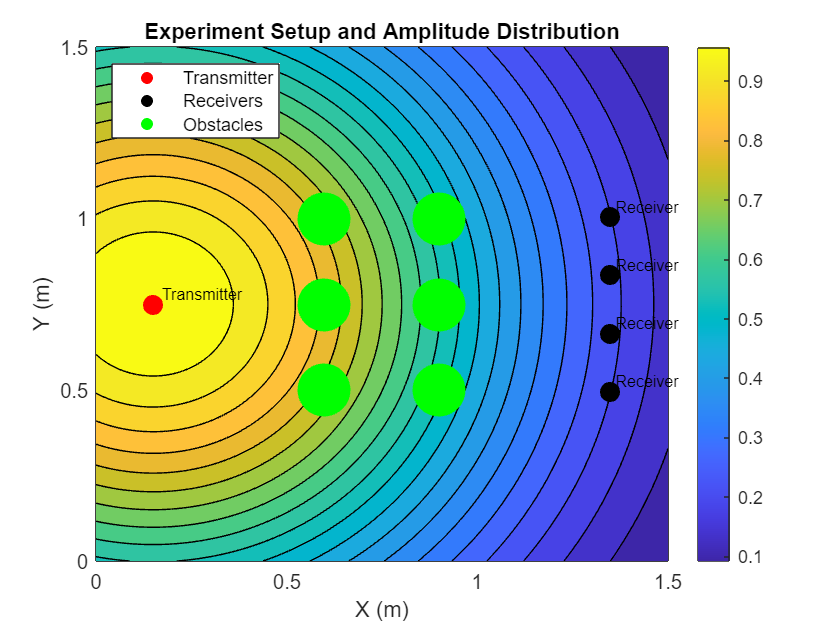

% Define table dimensions
table_length = 1.5;
table_width = 1.5;

% Define transmitter position
transmitter_x = 0.15;
transmitter_y = table_width / 2;

% Define receiver positions
receiver_x = repmat(table_length - 0.15, 1, 4); % Four receivers at the same x-coordinate
receiver_y = linspace(table_width / 2 - 3 * 0.17 / 2, table_width / 2 + 3 * 0.17 / 2, 4);

% Define cylindrical obstacles positions (two vertical rows with three each)
obstacle_row1_x = repmat(0.6, 1, 3);
obstacle_row1_y = linspace(table_width / 3, 2 * table_width / 3, 3);
obstacle_row2_x = repmat(0.9, 1, 3);
obstacle_row2_y = linspace(table_width / 3, 2 * table_width / 3, 3);

% Create figure
figure;
hold on;

% Draw table
rectangle('Position', [0, 0, table_length, table_width], 'EdgeColor', 'k');

% Simulate amplitude distribution
[X, Y] = meshgrid(linspace(0, table_length, 100), linspace(0, table_width, 100));
Z = exp(-((X - transmitter_x).^2 + (Y - transmitter_y).^2));

% Draw amplitude distribution
contourf(X, Y, Z, 20);
colorbar;

% Plot transmitter
scatter(transmitter_x, transmitter_y, 100, 'r', 'filled');
text(transmitter_x, transmitter_y, '  Transmitter', 'VerticalAlignment', 'bottom', 'FontSize', 8);

% Plot receivers
scatter(receiver_x, receiver_y, 100, 'k', 'filled');
for i = 1:length(receiver_x)
    text(receiver_x(i), receiver_y(i), ' Receiver', 'VerticalAlignment', 'bottom', 'FontSize', 8);
end

% Plot obstacles
scatter(obstacle_row1_x, obstacle_row1_y, 700, 'g', 'filled');
scatter(obstacle_row2_x, obstacle_row2_y, 700, 'g', 'filled');

% Labeling
title('Experiment Setup and Amplitude Distribution');
xlabel('X (m)');
ylabel('Y (m)');
legend({'','Transmitter', 'Receivers', 'Obstacles'}, 'Location', 'northwest');

hold off;

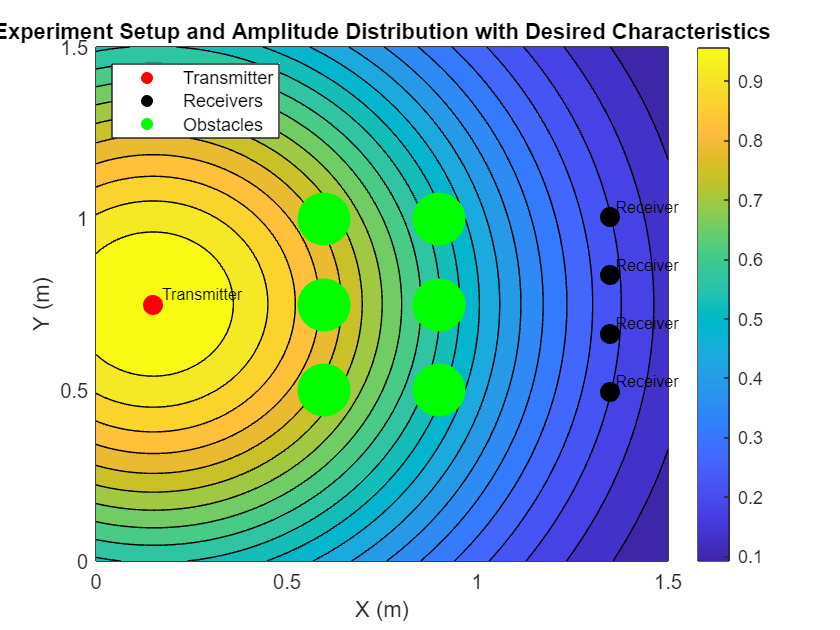

% Define table dimensions
table_length = 1.5;
table_width = 1.5;

% Define transmitter position
transmitter_x = 0.15;
transmitter_y = table_width / 2;

% Define receiver positions
receiver_x = repmat(table_length - 0.15, 1, 4); % Four receivers at the same x-coordinate
receiver_y = linspace(table_width / 2 - 3 * 0.17 / 2, table_width / 2 + 3 * 0.17 / 2, 4);

% Define cylindrical obstacles positions (two vertical rows with three each)
obstacle_row1_x = repmat(0.6, 1, 3);
obstacle_row1_y = linspace(table_width / 3, 2 * table_width / 3, 3);
obstacle_row2_x = repmat(0.9, 1, 3);
obstacle_row2_y = linspace(table_width / 3, 2 * table_width / 3, 3);

% Create figure
figure;
hold on;

% Draw table
rectangle('Position', [0, 0, table_length, table_width], 'EdgeColor', 'k');

% Simulate amplitude distribution with desired characteristics
[X, Y] = meshgrid(linspace(0, table_length, 100), linspace(0, table_width, 100));

% Initial amplitude distribution from the transmitter
Z_transmitter = exp(-((X - transmitter_x).^2 + (Y - transmitter_y).^2));

% Create a pattern of higher amplitudes at the upper and lower parts
Z_edges = exp(-((X - table_length / 2).^2 + ((Y - table_width * 2.5) - table_width).^2)) + ...
          exp(-((X - table_length / 2).^2 + ((Y + table_width * 2.5) - table_width).^2));

% Combine the patterns to get the desired distribution
Z = Z_transmitter + 0.5 * Z_edges;

% Draw amplitude distribution
contourf(X, Y, Z, 20);
colorbar;

% Plot transmitter
scatter(transmitter_x, transmitter_y, 100, 'r', 'filled');
text(transmitter_x, transmitter_y, '  Transmitter', 'VerticalAlignment', 'bottom', 'FontSize', 8);

% Plot receivers
scatter(receiver_x, receiver_y, 100, 'k', 'filled');
for i = 1:length(receiver_x)
    text(receiver_x(i), receiver_y(i), ' Receiver', 'VerticalAlignment', 'bottom', 'FontSize', 8);
end

% Plot obstacles with larger dots
scatter(obstacle_row1_x, obstacle_row1_y, 700, 'g', 'filled');
scatter(obstacle_row2_x, obstacle_row2_y, 700, 'g', 'filled');

% Labeling
title('Experiment Setup and Amplitude Distribution with Desired Characteristics');
xlabel('X (m)');
ylabel('Y (m)');
legend({'', 'Transmitter', 'Receivers', 'Obstacles'}, 'Location', 'northwest');

hold off;